V = VideoReader("C:\Users\Domodekavkaz\Documents\HoloDopplerFolders\240828_FIY0713_od_HD_0\avi\240828_FIY0713_od_HD_0_M0.avi");
video = zeros(V.Height, V.Width, V.NumFrames,'single');
[numX, numY, numFrames] = size(video);
for frameIdx = 1:V.NumFrames
    video(:, :, frameIdx) = rgb2gray(read(V, frameIdx));
end

clear V

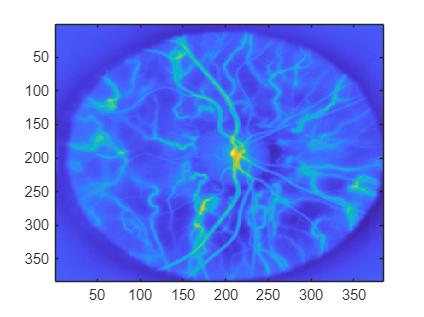


meanImg = mean(video,3);
imagesc(meanImg);

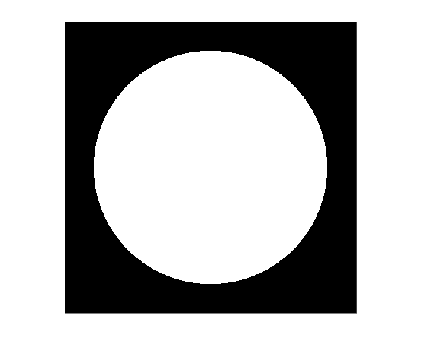

[x, y] = meshgrid(1:numX, 1:numY);
diaphragm = sqrt((x - numY/2) .^ 2 + (y - numX/2) .^ 2) <= 0.4 * (numX + numY) / 2;
imshow(diaphragm);

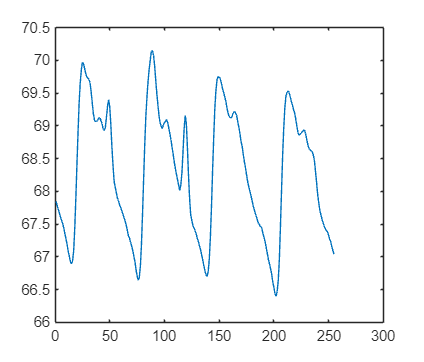

pulse = (sum(video.*diaphragm,[1,2])/nnz(diaphragm));
plot(squeeze(pulse));

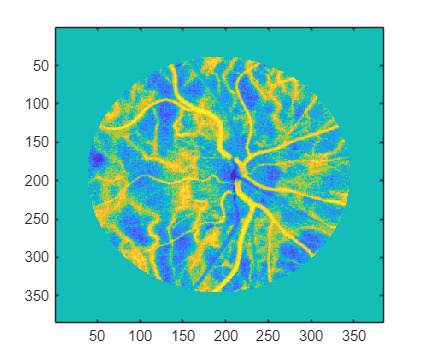

cor = mean((video-meanImg).*diaphragm .* (pulse-mean(pulse,3)),3)./(std((video-meanImg),[],3)*std(pulse-mean(pulse,3),[],3));
imagesc(cor);

threshold = 0.595;
num_parts = 6

num_parts = 6

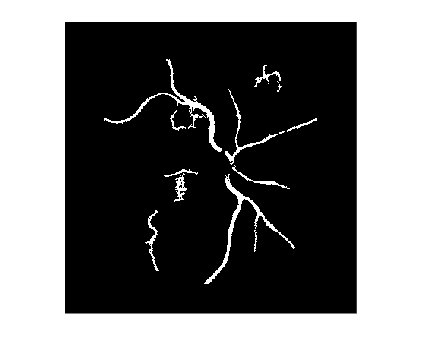

imshow(bwareafilt(cor>threshold,num_parts));

video_flat = reshape(video.*diaphragm,[numY*numX,numFrames]);
if true
    video_flat = normalize(video_flat,2);
end
video_flat(~reshape(diaphragm,[1 numY*numX]))=NaN;
[idx,C,~,~] = kmeans(video_flat,6,'Distance',"correlation",'MaxIter',2000);

kmeans requires Statistics and Machine Learning Toolbox.

idx = reshape(idx,[numY,numX]);

imagesc(idx);

m=0;
idxArtery = 0;
for c = 1:size(C,1)
    plot(C(c,:));
    hold on
    if sum(cor.*(idx==c),[1,2])>m
        m=sum(cor.*(idx==c),[1,2]);
        idxArtery = c;
    end
end
title('Centroids (waveform in each label)')
hold off
imagesc(cor.*(idx==idxArtery))

L = idx;
[x, y] = meshgrid(1:numX, 1:numY);
positions = cat(3,x,y);
positions = reshape(positions,numY*numX,[]);
%positions(~reshape(diaphragm,[1 Nx*Ny]),:)=[];
nn_indicies = knnsearch(positions,positions,Distance='euclidean',K=19);
new_L = mode(L(nn_indicies),2);
new_L = reshape(new_L,numY,numX);
imagesc(new_L)

mask=bwareafilt(cor>0.29&bwareafilt((new_L==idxArtery),8),7);
imshow(mask)